# Hexapod simulation

## Create maze

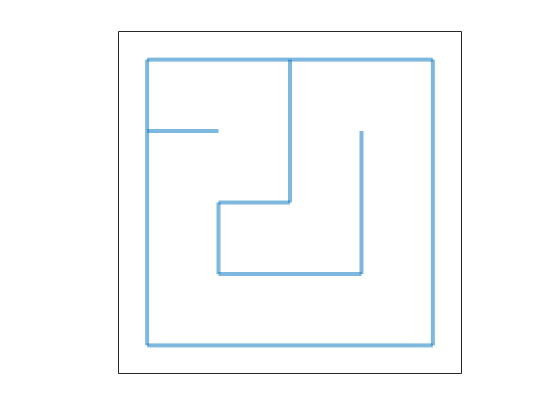

close all
clear all
clc
branching = 5;
mazeCreator(branching,'middle',false,false);
pad = 24;
maze = getframe(gca).cdata(pad:end-pad,pad:end-pad,1);

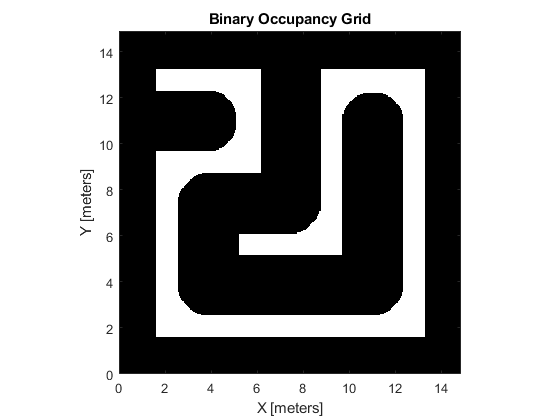

%turn maze into occupancy grid
maze = imbinarize(maze);
maze = imcomplement(maze);
res = 20;
map = binaryOccupancyMap(maze, res);

robotBoundingRadius =1.2;
map.inflate(robotBoundingRadius);
figure;
show(map)

## Setup state space and planner

%SE(2) state space - rotation not relevant
ss = stateSpaceSE2;
ss.StateBounds = [map.XLocalLimits; map.YLocalLimits; -pi pi];
validator = validatorOccupancyMap(ss);
validator.Map = map;

%RRT* planner
planner = plannerRRTStar(ss,validator);
planner.MaxIterations=1e6;
planner.MaxNumTreeNodes=1e6;
planner.MaxConnectionDistance = 1;

 

## Plan path

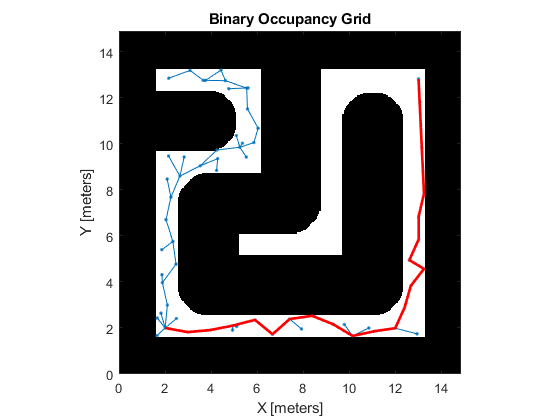

startPose = [2 2 0]; 
goalPose = [13 13 0];

% lidar parameters
sensOff = [0 0];
maxSenRange = 6;
sensDegRes = 2;


[refpath, solnInfo] = plan(planner, startPose, goalPose);
map.show;
hold on;
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2), '.-'); % tree expansion
plot(refpath.States(:,1),refpath.States(:,2),'r-','LineWidth',2); % draw path


waypoints = refpath.States(:,1:2);

 

## Run simulation

Ts = 0.1;
Tf = 50;
open_system('hexapod_lidar');
simout = sim('hexapod_lidar', [0 Tf]);
time = linspace(0, Tf, length(simout.yout{1}.Values))

time = 50

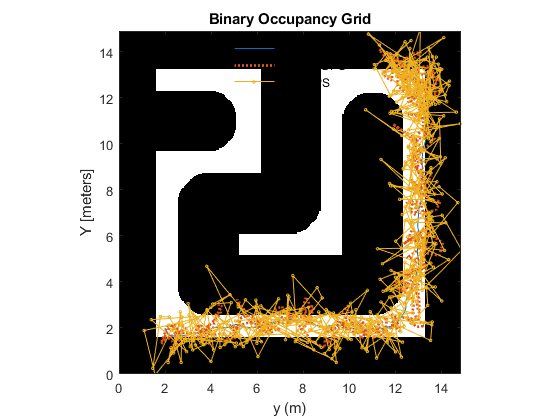

state = simout.yout{1}.Values.Data;
state_KF = simout.yout{2}.Values.Data;
state_GPS = simout.yout{3}.Values.Data;
plotPathHelper(map, state, state_KF, state_GPS)

## Lidar & SLAM

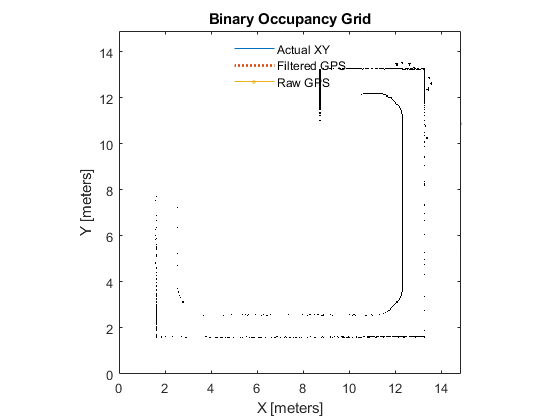

%lidar
lidar_poses = simout.yout{4}.Values.Data;
lidar_ranges = simout.yout{5}.Values.Data;

lidar_ranges = squeeze(lidar_ranges);

lidar_angles = [ 0:sensDegRes*pi/180:2*pi-(sensDegRes*pi/180)];

% initialise empty map
lidar_map = binaryOccupancyMap(zeros(size(maze)), res);

for idx = 1:size(lidar_poses,1)
    scan(idx) = lidarScan(lidar_ranges(:,idx), lidar_angles);
    insertRay(lidar_map, lidar_poses(idx,:) , scan(idx), maxSenRange);
end

show(lidar_map)

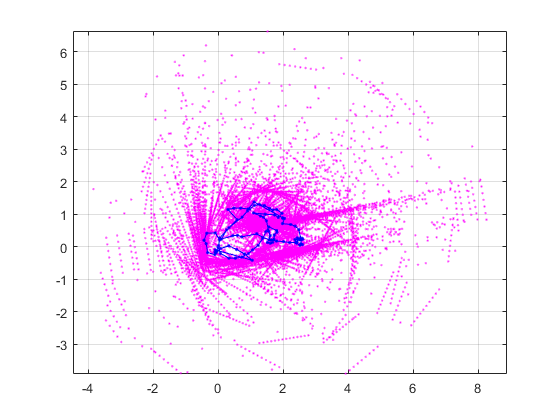


%SLAM
slamAlg = lidarSLAM(res, maxSenRange);
for i=1:size(lidar_poses,1) %here I add the scans to the SLAM, I tried to compute the relative pose as the following pose in lidar_pose minus previous pose in the SLAM (and corrected the offset of [2 2 0])
    if i>1
     [exScans, exPoses]  = scansAndPoses(slamAlg);
    relative_pose=lidar_poses(i,:)-[2 2 0]-exPoses(end,:); %sometimes this causes the program to crash
    [isScanAccepted(i), loopClosureInfo, optimizationInfo] = addScan(slamAlg, scan(i),relative_pose);
    else
        relative_pose=lidar_poses(1,:)-[2 2 0];
     [isScanAccepted(i), loopClosureInfo, optimizationInfo] = addScan(slamAlg, scan(1),relative_pose);   
    end
end

figure
show(slamAlg);

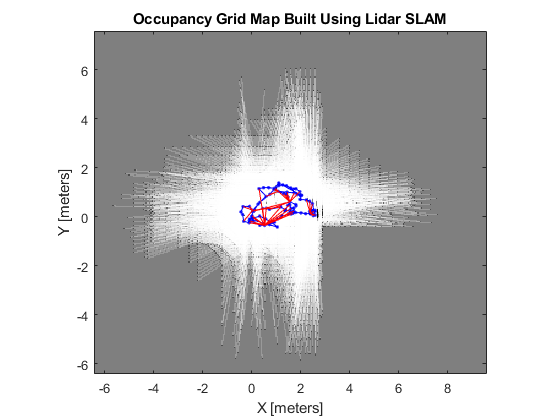


[scans, optimizedPoses]  = scansAndPoses(slamAlg); %NOTE: the estimated poses have a rotation different from 0, so I just put 0
optimizedPoses(:,3)=zeros(size(optimizedPoses,1),1);
mapSlam = buildMap(scans, optimizedPoses, res, maxSenRange);

figure; 
show(mapSlam);
hold on
show(slamAlg.PoseGraph, 'IDs', 'off');
hold off
title('Occupancy Grid Map Built Using Lidar SLAM');

## Helper functions

function plotPathHelper(map, state, state_KF, state_GPS)
    figure;
    map.show;
    hold on
    plot(state(:,1), state(:,2))
    plot(state_KF(:,1), state_KF(:,2),':', 'linewidth',2)
    plot(state_GPS(:,1), state_GPS(:,2), 'o-','markersize',2)
    box on
    legend('Actual XY', 'Filtered GPS', 'Raw GPS')
    legend box off
    xlabel 'x (m)'
    xlabel 'y (m)'
    legend location best
end
function [time, state, state_KF, state_GPS] = extractSimOutHelper(simout, Tf)

time = linspace(0, Tf, length(simout.yout{1}.Values.Data(:,1)));
state = simout.yout{1}.Values.Data;
state_KF = simout.yout{2}.Values.Data;
state_GPS = simout.yout{3}.Values.Data;

end

function plotErrorHelper(Tf, time, state, state_KF, state_GPS)
timeIntrp = linspace(0, Tf, size(state_KF,1));
xIp = interp1(time, state(:,1), timeIntrp)';
yIp = interp1(time, state(:,2), timeIntrp)';

figure, tiledlayout(2,1)
nexttile, hold on, plot(timeIntrp, xIp - state_GPS(:,1)), plot(timeIntrp, yIp - state_GPS(:,2)), ylim([-3 3]), title('raw gps error'), box on, text(2, 1.7, "mean abs error = " + num2str(0.5*mean(abs(xIp - state_GPS(:,1))) + 0.5*mean(abs(yIp - state_GPS(:,2)))))
nexttile, hold on, plot(timeIntrp, xIp - state_KF(:,1)),  plot(timeIntrp, yIp - state_KF(:,2)), ylim([-3 3]), title('filtered gps error'), box on,  text(2, 1.7, "mean abs error = " + num2str(0.5*mean(abs(xIp - state_KF(:,1))) + 0.5*mean(abs(yIp - state_KF(:,2)))))
end